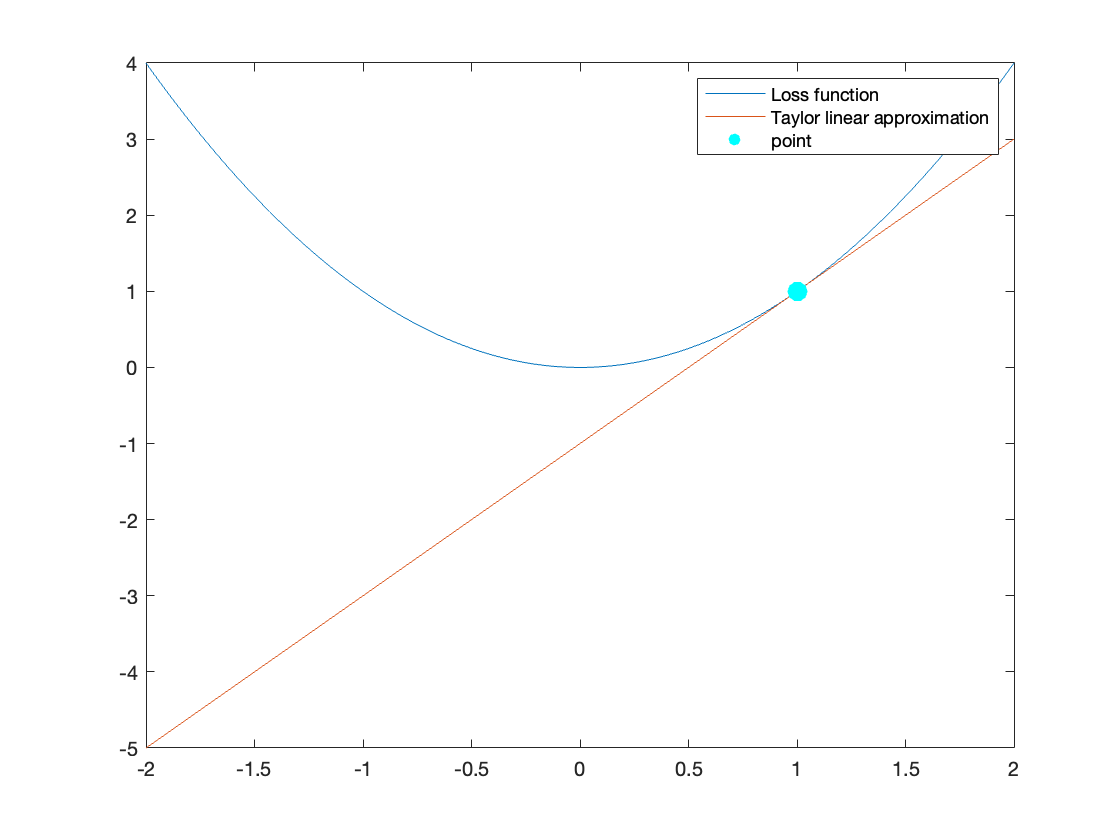

x_range = -2:1e-2:2;

% loss function
f = @(x) x.^2;
% graident point
x0 = 1;
% graident function
g = @(x) 2.*x;
% linear approximation function
f1 = @(delta) f(x0) + (delta-x0).*g(x0);

plot(x_range,f(x_range),x_range,f1(x_range))
hold on
scatter(x0, f(x0), 100, 'filled', "MarkerFaceColor",'c')
legend('Loss function','Taylor linear approximation', 'point')
hold off